# Giraffe ADC Testbench

## Serial 串口的申请与调用

clear 
clc

serialportlist

ans = "COM3"


baudrate = 115200;
% data_in = zeros();

s = serialport("COM3",baudrate)

s =   Serialport - 属性:

                 Port: "COM3"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions



data = read(s,4*100000,'uint8')

data =     43     7     9   193    28    42    48   229    48     1    39   198    44     6     2   231    28    41    39   193    47     0     4   225    45     5    34   201    28    40    41   198    46     1    36   195    46     4     1   227    28    40    41   201    45     1     7   226    47     3



if (s.NumBytesAvailable == 0)
    disp("Data reading from Serial Port Ready!")
end

Data reading from Serial Port Ready!


## 串口数据后处理

% 将uint8 -> dec 
% data_origin = dec2bin(s.UserData); 
data_origin = dec2bin(data);
data_tag = data_origin(:,1:2);


if (sum(mod(find(data_tag=='11'), 4)) > 0 )
    disp("Data Missing!");
    index = find(data_tag == '11');
    index_mod = mod(index, 4);
    fprintf("Missing data occured at %d sampled point;\n",find(index_mod ~= 0, 3))
    
else
    disp("Data Right!");
end

Data Right!


clear s;

data_sign = str2num(data_origin(:,3));
data_value = data_origin(:,4:end);

data_sign(data_sign==1) = -1;
data_sign(data_sign==0) = 1;
data_value = bin2dec(data_value) .* data_sign;

N_Sample = length(data_value) / 4;
data_N4 = reshape(data_value, [4, N_Sample])'

data_N4 =    -11     7     9     1
    28   -10   -16    -5
   -16     1    -7     6
   -12     6     2    -7
    28    -9    -7     1
   -15     0     4    -1
   -13     5    -2     9
    28    -8    -9     6
   -14     1    -4     3
   -14     4     1    -3


## Calibration

% ~~~~~~~~~~~~~~~ test environment ~~~~~~~~~~~~~~~
% clk_50M = 50E6;
% clk_adc = clk_50M / 5_000 ;
% fs = clk_adc / 50;

gain = deltaGain(data_N4(:,2:end), 10)

gain =    15.2817
   15.2860
   15.2903
   15.2903
   15.2817
   15.2990
   15.2817
   15.2838
   15.2903
   15.2817




% ~~~~~~~~~~~~~~~ display result ~~~~~~~~~~~~~~~
GAIN = mean(gain)

GAIN = 15.2842

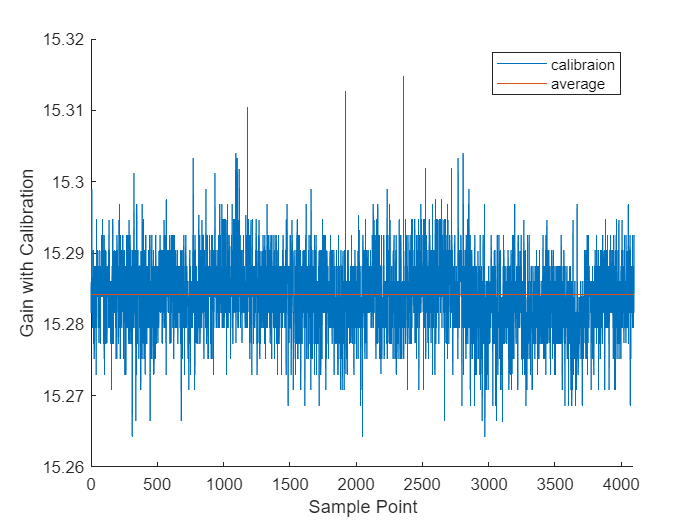


figure
hold on;
plot(gain);
plot(ones([1,N_Sample/2])*GAIN)
hold off;
xlim([0, N_Sample/2]);

legend(["calibraion", "average"], ...
    'Location', 'northeast')
xlabel("Sample Point");
ylabel("Gain with Calibration");

## AC Low Speed

Vref = 1.8;
N_SUB = 5;
LSB_SUB = 1.8 / 2^N_SUB;

fclock = 50E6 / 1;              % clk_adc = 10kHz;
fprintf("Number of Sample Points: 64 *  16 tiems average;")

Number of Sample Points: 64 *  16 tiems average;

fs = fclock / 25                % sample rate = 200Hz;

fs = 2000000

fin = 1/256*fs                  % fin = 5/64*fs;

fin = 7.8125e+03


Vout_N4 = data_N4 * LSB_SUB

Vout_N4 =    -0.6188    0.3937    0.5062    0.0563
    1.5750   -0.5625   -0.9000   -0.2812
   -0.9000    0.0563   -0.3937    0.3375
   -0.6750    0.3375    0.1125   -0.3937
    1.5750   -0.5062   -0.3937    0.0563
   -0.8438         0    0.2250   -0.0563
   -0.7313    0.2812   -0.1125    0.5062
    1.5750   -0.4500   -0.5062    0.3375
   -0.7875    0.0563   -0.2250    0.1688
   -0.7875    0.2250    0.0563   -0.1688


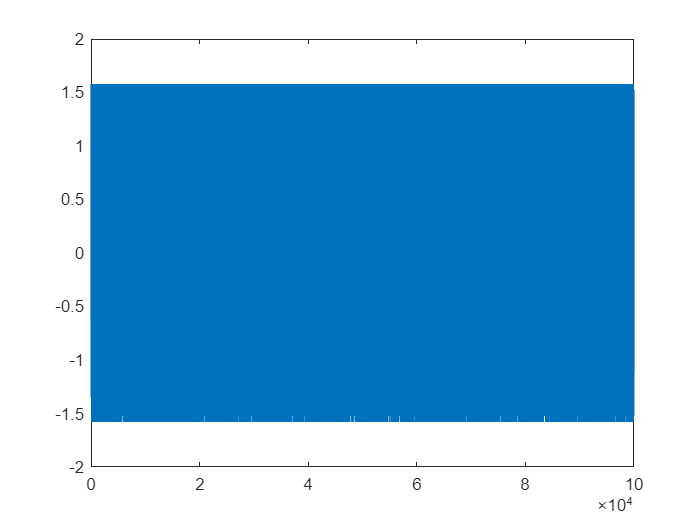

% ~~~~~~~~~~~~~~~ Flash ~~~~~~~~~~~~~~~
figure
plot(Vout_N4(1:end,1));

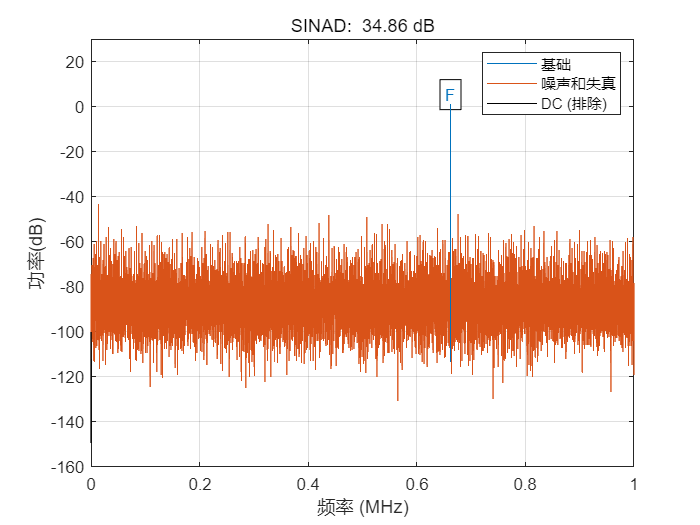

sinad(Vout_N4(:,1), fs);

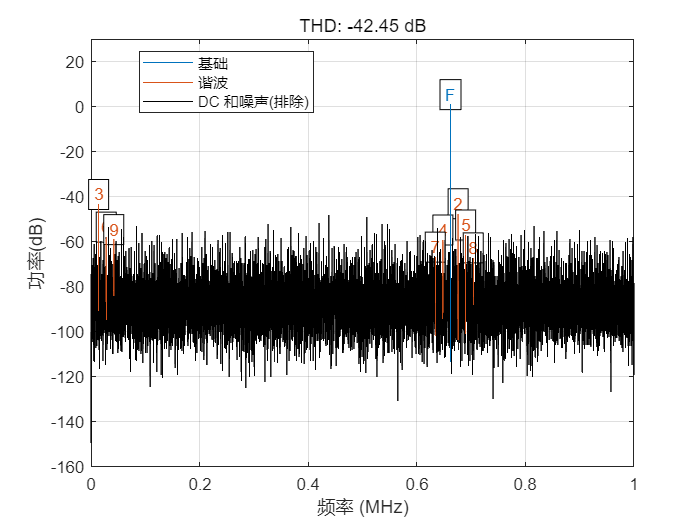

ans = -42.4534

thd(Vout_N4(:,1), fs, 9, 'aliased')

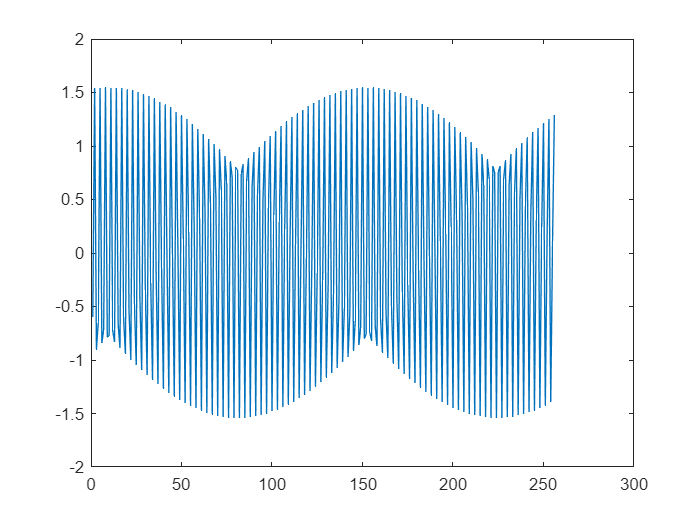

% ~~~~~~~~~~~~~~~ without calibration ~~~~~~~~~~~~~~~
Vout_without_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_without_calib(i) = Calib_Gain(Vout_N4(i,:), 16);
end
plot(Vout_without_calib(1:256,1));

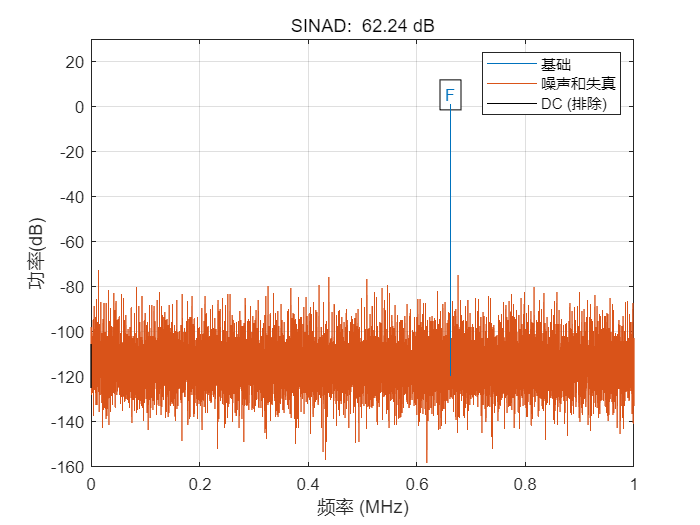

ans = 62.2389

sinad(Vout_without_calib, fs)

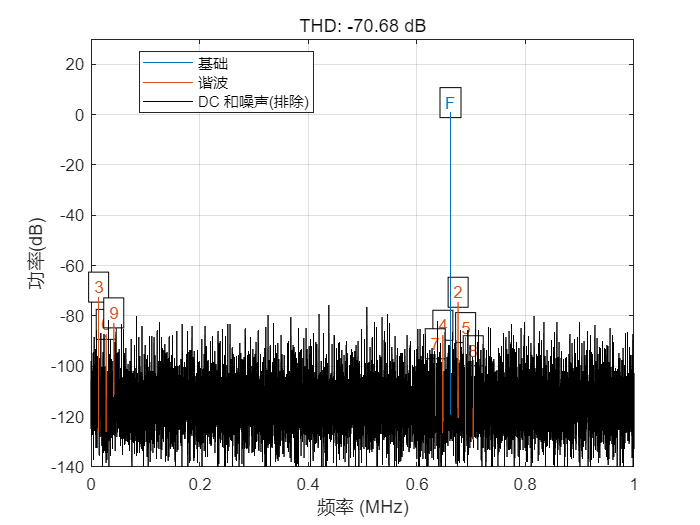

ans = -70.6842

thd(Vout_without_calib, fs, 9, 'aliased')

## Calibration

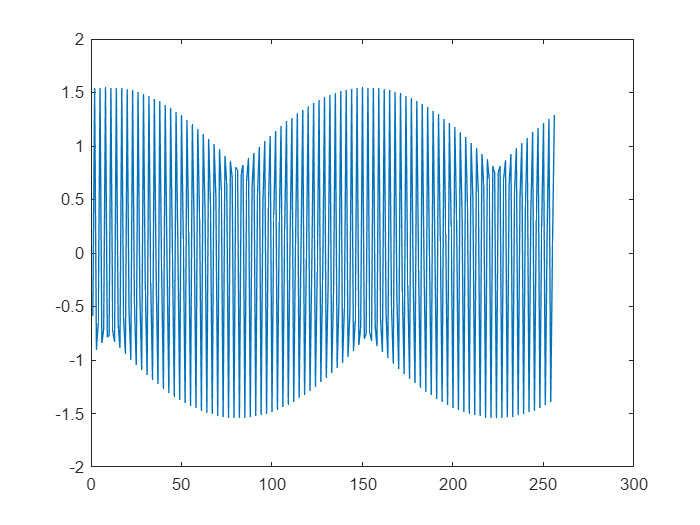

Vout_mean_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), GAIN);
%     Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), 15.4);
end
plot(Vout_mean_calib(1:256,1));

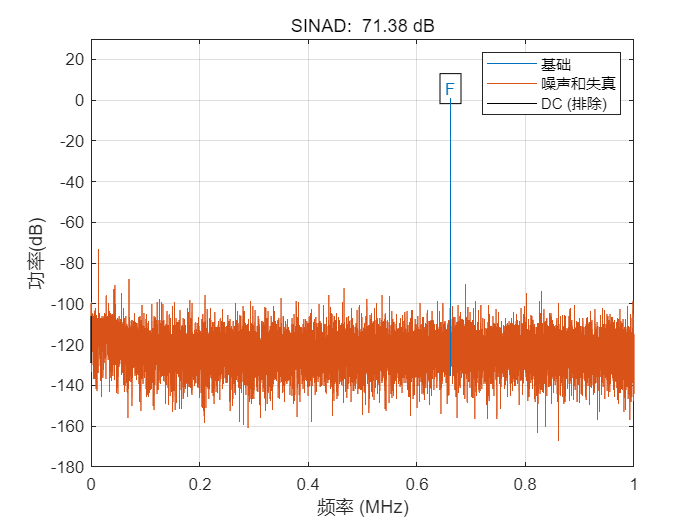

ans = 71.3831

sinad(Vout_mean_calib, fs)

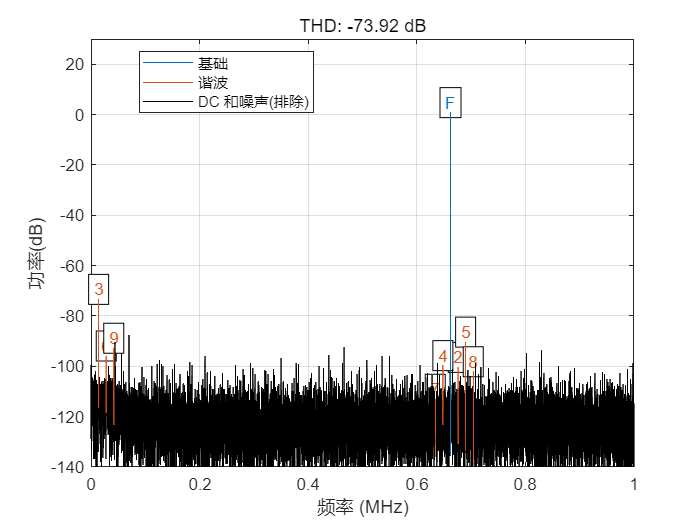

ans = -73.9181

thd(Vout_mean_calib , fs, 9, 'aliased')

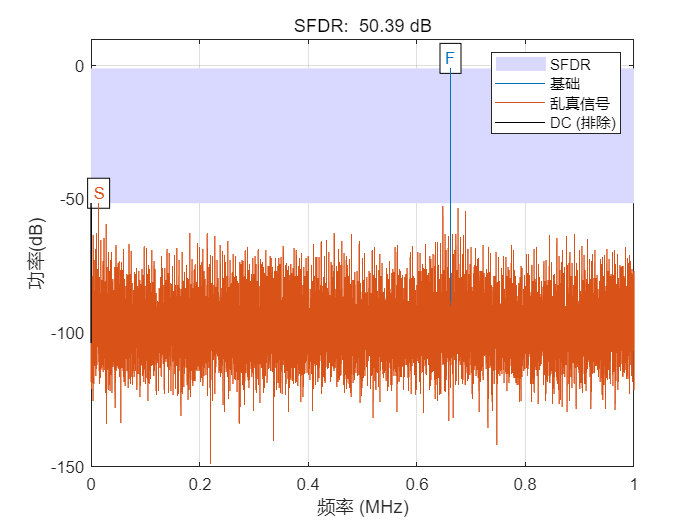

ans = 74.1028

sfdr(Vout_mean_calib, fs)

## Data Process

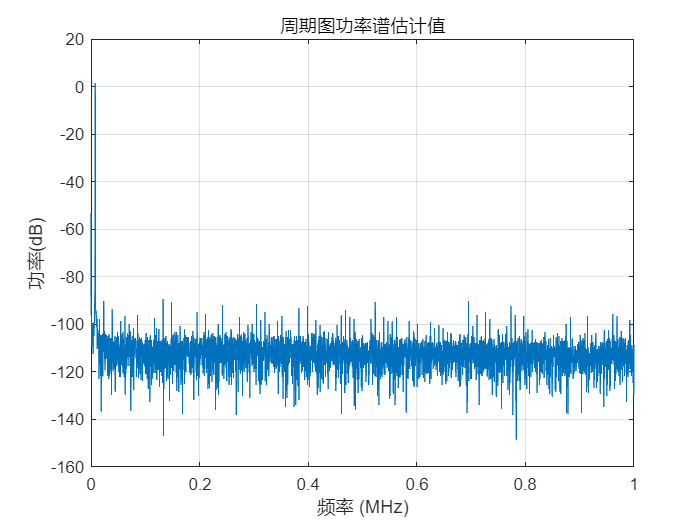

figure
periodogram(Vout_mean_calib, ...
        rectwin(N_Sample), N_Sample, fs, 'Power');

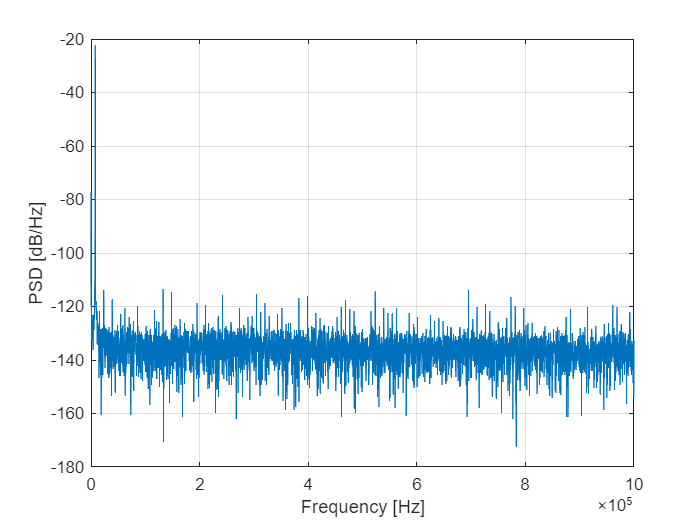


[pxx, f] = periodogram(Vout_mean_calib, ...
        rectwin(N_Sample), N_Sample, fs, 'PSD');x
figure
plot(f, 10*log10(pxx));f
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]')
grid on

% title(['Noise Floor: ', num2str(Noise_RMS), ' dB'])

## Gain Sweep

gain_sweep = 14:0.01:17;
sinad_sweep = zeros(size(gain_sweep));
thd_sweep = zeros(size(gain_sweep));
for j = 1:length(gain_sweep)
    Vout_sweep = zeros(N_Sample, 1);
    for i=1:N_Sample
        Vout_sweep(i) = Calib_Gain(Vout_N4(i,:), gain_sweep(j));
    end
    sinad_sweep(j) = sinad(Vout_sweep, fs);
    thd_sweep(j) = thd(Vout_sweep, fs, 7, 'aliased');
end

max(sinad_sweep)

ans = 74.1675

min(thd_sweep)

ans = -86.5993

find(sinad_sweep == max(sinad_sweep))

ans = 133

find(thd_sweep == min(thd_sweep))

ans = 138

gain_sweep(133)

ans = 15.3200

gain_sweep(137)

ans = 15.3600

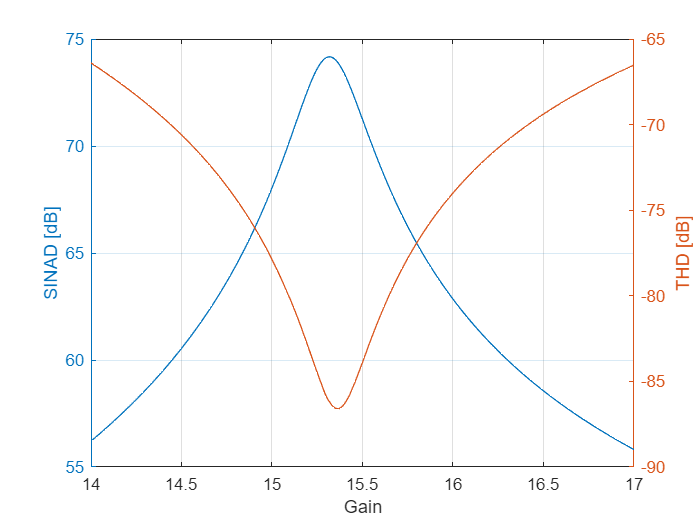

figure
yyaxis left
plot(gain_sweep, sinad_sweep);

ylabel("SINAD [dB]")
yyaxis right
plot(gain_sweep ,thd_sweep)
ylabel("THD [dB]")
xlabel("Gain")
grid on

## Noise Analysis

% [f, p, NV_rms] = Noise_PSD(Vout_without_calib, fs);
% figure
% plot(f, 10*log10(p));
% grid on;
% % Periodgram
% 
% periodogram(Vout_without_calib, ...
%         rectwin(N_Sample), N_Sample, fs, 'PSD');
% 
% PsdSectionLength = 2048;
% NumSection = N_Sample / PsdSectionLength;
% PSD = [];
% for i=1:NumSection
%     index_head = (i-1)*PsdSectionLength+1;
%     index_tail = i*PsdSectionLength;
%     [pxx,f ] = periodogram(Vout_without_calib(index_head:index_tail), ...
%         hann(PsdSectionLength), N_Sample, fs, 'PSD');
%     PSD = [PSD,pxx];
% end
% PSD_AVE = mean(PSD,2);
% figure
% plot(f, 10*log10(PSD_AVE));
% xlabel('Frequency [Hz]');
% ylabel('PSD [dB/Hz]')
% grid on
% %integrated Noise
% Noise_RMS = sqrt(sum(PSD_AVE*(fs/(N_Sample))))

% Integrated Noise in Power
Noise_RMS = pow2db(var(Vout_mean_calib))

Noise_RMS = -88.4889

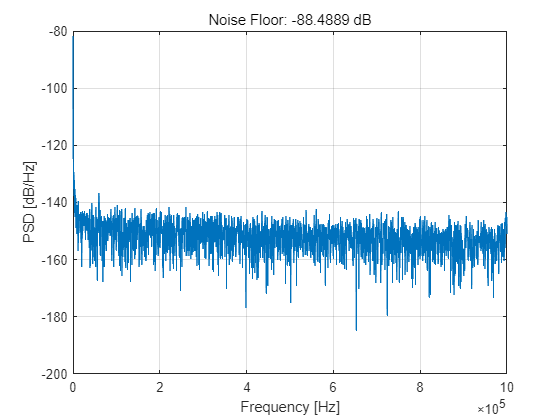

% Periodgram

[pxx, f] = periodogram(Vout_mean_calib, ...
        rectwin(N_Sample), N_Sample, fs, 'PSD');

figure
plot(f, 10*log10(pxx));
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]')
grid on
title(['Noise Floor: ', num2str(Noise_RMS), ' dB'])
% pxx(1) = 0;
% % pow2db(sum(p1 * (fs/N_Sample)))
% offset = mag2db(mean(Vout_without_calib))

## Dynamic Range

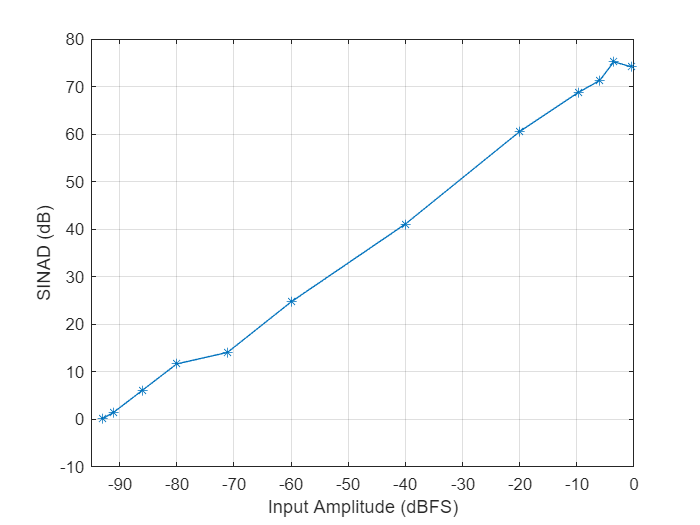

Vin_dBFS = [-0.496471675
    -3.521825181
    -6.020599913
    -9.688409869
    -20
    -40
    -60
    -71.12605002
    -80
    -86.02059991
    -91.12605002
    -93.06425028];
DR_SINAD = [
    74.16
    75.21
    71.26
    68.8
    60.54
    41.09
    24.71
    14.09
    11.68
    6.12
    1.42
    0.11];
figure
plot(Vin_dBFS, DR_SINAD, '*-'); 
grid on;
ylim([-10, 80])
xlim([-95, 0])
xlabel('Input Amplitude (dBFS)');
ylabel('SINAD (dB)')

function serial_callback(s, ~)
%     global data_serial;
    data = read(s, 1, 'uint8');
    s.UserData = [s.UserData; data];
    % 通过串口对象自身将读取数据带回；
    disp(data)
end